# BIOL 450 Assignment 4: Population Coding

Cathy Zhuang

Dr. Berman

20 February 2022

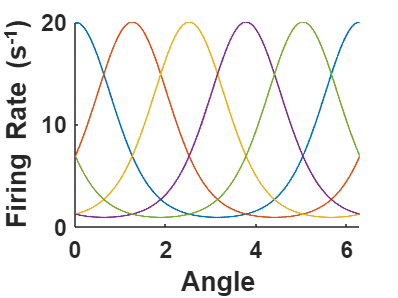

%% 0
% Add the code from Canvas to your path and use drawReceptiveFields(N) to
% draw N evenly space receptive fields. Try performing this for N = 5, 10,
% 15, and 20 to get a sense of the receptive fields.

drawReceptiveFields(5,[],[]);

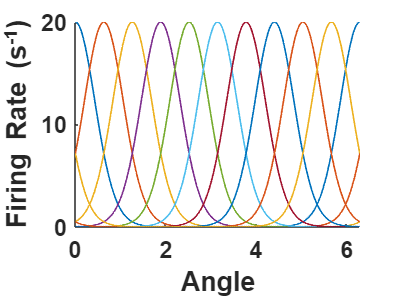

drawReceptiveFields(10,[],[]);

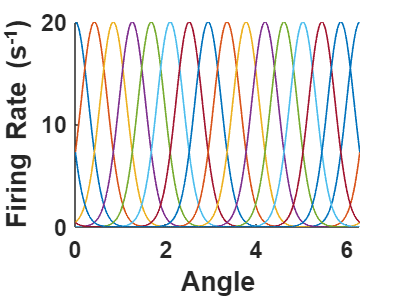

drawReceptiveFields(15,[],[]);

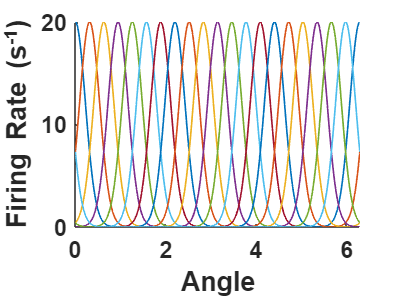

drawReceptiveFields(20,[],[]);

### Question 1

* If *$y={\textrm{Ax}}^m$* show that log y ∝ m log x.*


$$y={\textrm{Ax}}^m$$



$$\begin{array}{l}
\log \;y=\log \;\left({\mathrm{Ax}}^m \right)\\
\log \;y=\log \left(A\right)+\log \left(x^m \right)\\
\log \;y=\log \left(A\right)+m\;\log \left(x\right)\\
\log \;y\propto m\;\log \left(x\right)
\end{array}$$


### Question 2

*Use [outputValues,∼] = histogramMLEstimates(s,N,rMax,deltaT) to plot the distribution of maximum likelihood estimates using the population code for s = 1 given N = 10 neurons, a maximum firing rate (rmax) of 20, and a measurement time (∆t) of 2. Report the mean (< *$\hat{s}$* > ) and standard deviation (σest(*$\hat{s}$*)) of the distribution. Does the distribution look gaussian? (Note: outputValues is an array of all simulated estimated values. This will come in handy in a moment.)*

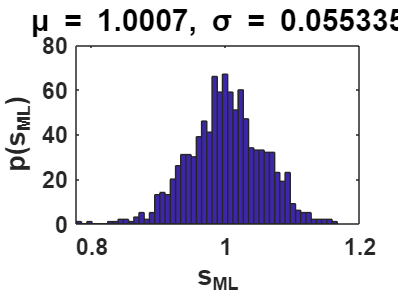

[outputValues, ~] = histogramMLEstimates(1, 10, 20, 2, [], [], []);

        The mean is around 1, and the standard deviation is around 0.05.

        The distribution does look gaussian, as it forms the shape of a bell curve.

### Question 3

*What is the estimate’s normalized error for your results in the previous problem. Are these results consistent with those of an unbiased estimator? *

normalizedError = (mean(outputValues) - 1)/std(outputValues);
disp(normalizedError)

    0.0131



 The normalized error is small (the number displayed above), which is consistent with those of an unbiased estimator, since the normalized error here is closer to zero.

### Question 4

The Cramer-Rao bound for this system is given by ..., where σ is the width of a single tuning curve. Using this information, estimate the smallest possible ∆t you would need to have σest(s) < 10^−4 (all other parameters remaining the same). Confirm this finding by plugging this value into the above function (note that σ = π/N here).

syms Deltat
disp(vpa(solve(10^-8 == (sqrt(2*pi*((pi/10)^2)))/((10^2) * 20 * Deltat), Deltat)))

$$39374.024864306045312645210287883$$

        Delta t = 39374.0248643

[outputValues1, ~] = histogramMLEstimates(1, 10, 20, 39374.0248643, [], pi/10, []);

### Question 5

*Calculate and plot (< s >ˆ −s) and σ 2 est(ˆs) as a function of N for N = 5, 10, 15, . . . , 50 (using [outputValues,∼] = histogramMLEstimates(s,N,rMax,deltaT,[],[],false) to suppress plots). Again, use s = 1, ∆t = 2, and rmax = 20.*

increments = 5:5:50

increments =      5    10    15    20    25    30    35    40    45    50


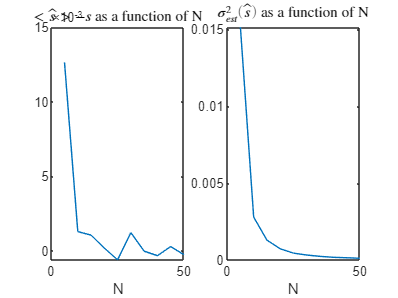

for iN = increments
    [outputValues2,~] = histogramMLEstimates(1,iN,20,2,[],[],false); 
    means(find(increments==iN),:) = mean(outputValues2)-1; 
    vars(find(increments==iN)) = var(outputValues2);
end


subplot(1,2,1)
plot(increments, means);
title('$<\hat{s}> - s$ as a function of N','Interpreter','latex');
xlabel('N');

subplot(1,2,2);
plot(increments, vars);
title('$\sigma^{2}_{est}(\hat{s})$ as a function of N','Interpreter','latex');
xlabel('N');
hold off

### Question 6

*Plot log σ^2 est(ˆs) vs. log N from the previous question and calculate the slope of the resulting line. Do these results agree with your intuition from the Cramer-Rao bound? Explain your reasoning.*

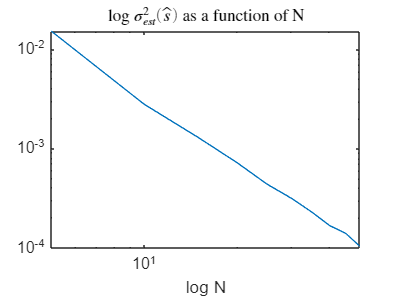

figure
loglog(increments, vars);
title('log $\sigma^{2}_{est}(\hat{s})$ as a function of N','Interpreter','latex');
xlabel('log N');


B = polyfit(log(increments), log(vars), 1);
disp(B(1,1));

   -2.1132



The slope is around -2. As log N increases, the log error decreases by about 2. This agrees with our intuition because N is used in the Cramer-Rao bound calculation as N^2 in the denominator. Thus, as the N^2 increases in the denominator, our variance overall decreases, and so our lower bound on the variance will also be smaller.

### Question 7

*Now we will probe how altering σ, the tuning curve width, affects σ 2 est(s). Use [outputValues,∼] = histogramMLEstimates(s,N,rMax,deltaT,[],sigma,false) to find σ 2 est(s) for σ = 0.08, 0.10, 0.12, . . . , 0.98, 1.00. Once more, use s = 1, ∆t = 2, and rmax = 20. Plot σ 2 est(s) vs. σ on a semi-log axis (semilogy in Matlab). You should find that the curve is non-monotonic. At what value of σ is the function minimized?*

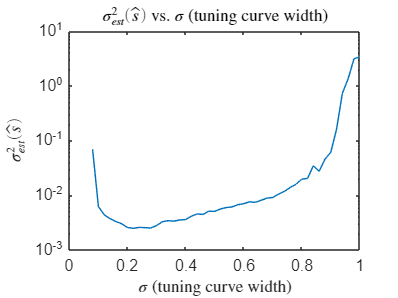

increments2 = 0.08:0.02:1;
vars2 = nan(size(increments2));
std3 = nan(size(increments2));

for sig = increments2
    [outputValues3,~] = histogramMLEstimates(1,10,20,2,[],sig,false); 
    vars2(increments2==sig) = var(outputValues3);
    std3(increments2==sig) = std(outputValues3);
end

figure
semilogy(increments2, vars2);
title('$\sigma^{2}_{est}(\hat{s})$ vs. $\sigma$ (tuning curve width)','Interpreter','latex');
xlabel('$\sigma$ (tuning curve width)','Interpreter','latex');
ylabel('$\sigma^{2}_{est}(\hat{s})$','Interpreter','latex');

    The function is minimized at sigma = 0.22. This means that at a tuning curve width of 0.22, our variance is the smallest.

### Question 8

*Use drawReceptiveFields(N,rMax,sigma) to draw the receptive fields for the value of σ that you found in the previous question.*

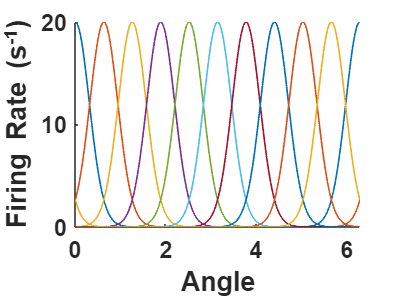

drawReceptiveFields(10,20,0.22);

### Question 9

*Give an intuitive explanation (no equations allowed) as to why there should be an optimal value for σ, rather than the optimal value being infinitely large or infinitesimally small.*

There should be an optimal value for the width of the tuning curve (sigma) because being either too large or too small produces inconclusive results. If the tuning curve width is infinitesimally small, there will be gaps where no neuron is firing, and it will be difficult to determine what exactly is going on. If the tuning curve width is too large, there is too much overlap between the curves, again making it difficult to determine what exactly is going on. The variance for both will be very high.